# Derivation of equations of motion for Kasdin & Paley Problem 11.11

## Set up all constant and time varying values

syms R g l m_r 'positive'
syms N1 N2 N3 tau J psidd thdd 'real'
syms theta(t) psi(t) phi(t)

## Set up standard DCMs

rotMatE3 = @(ang) [cos(ang) sin(ang) 0;-sin(ang) cos(ang) 0;0 0 1];
rotMatE2 = @(ang) [cos(ang) 0 -sin(ang);0 1 0;sin(ang) 0 cos(ang)];
rotMatE1 = @(ang) [1 0 0;0 cos(ang) sin(ang);0 -sin(ang) cos(ang)];
rotMats = {rotMatE1,rotMatE2,rotMatE3};

## Define direction cosine matrices and angular velocities for $\psi$ rotation about $\mathbf{e}_3$ and $-\theta$  rotation about $\mathbf{b}_2$

bCi = rotMats{3}(psi) % I->B

$$bCi(t) = \left(\begin{array}{ccc} \cos\left(\psi \left(t\right)\right) & \sin\left(\psi \left(t\right)\right) & 0\\ -\sin\left(\psi \left(t\right)\right) & \cos\left(\psi \left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

cCb = rotMats{2}(-theta) % B->C

$$cCb(t) = \left(\begin{array}{ccc} \cos\left(\theta \left(t\right)\right) & 0 & \sin\left(\theta \left(t\right)\right)\\ 0 & 1 & 0\\ -\sin\left(\theta \left(t\right)\right) & 0 & \cos\left(\theta \left(t\right)\right) \end{array}\right)$$

iWb = [0;0;diff(psi,t)] %B frame

$$iWb(t) = \left(\begin{array}{c} 0\\ 0\\ \frac{\partial }{\partial t}\psi \left(t\right) \end{array}\right)$$

bWc = [0;-diff(theta,t);0] %C frame

$$bWc(t) = \left(\begin{array}{c} 0\\ -\frac{\partial }{\partial t}\theta \left(t\right)\\ 0 \end{array}\right)$$

## Apply Euler's second law to the disk, assuming planar moment of inertia $J$ about $\mathbf{b}_3$ - all in $\mathcal{B}$ frame

h_O = J*iWb

$$h\_O(t) = \left(\begin{array}{c} 0\\ 0\\ J\,\frac{\partial }{\partial t}\psi \left(t\right) \end{array}\right)$$

M_O = cross([0;R;0],[-N1;-N2;N3])

$$M\_O = \left(\begin{array}{c} N_{3}\,R\\ 0\\ N_{1}\,R \end{array}\right)$$

eq1 = (diff(h_O,t)+cross(iWb,h_O) ==  M_O)

$$eq1(t) = \left(\begin{array}{c} 0=N_{3}\,R\\ 0=0\\ J\,\frac{\partial^{2}}{\partial t^{2}}\psi \left(t\right)=N_{1}\,R \end{array}\right)$$

eq1 = eq1(t)

$$eq1 = \left(\begin{array}{c} 0=N_{3}\,R\\ 0=0\\ J\,\frac{\partial^{2}}{\partial t^{2}}\psi \left(t\right)=N_{1}\,R \end{array}\right)$$

psiddeom = solve(subs(eq1(3),diff(psi,t,t),psidd),psidd)

$$psiddeom = \frac{N_{1}\,R}{J}$$

## Rod kinematics in $\mathcal{B}$ frame components

r_GO = [0;R;0] + transpose(cCb)*[0;0;l/2]

$$r\_GO(t) = \left(\begin{array}{c} -\frac{l\,\sin\left(\theta \left(t\right)\right)}{2}\\ R\\ \frac{l\,\cos\left(\theta \left(t\right)\right)}{2} \end{array}\right)$$

v_GO = diff(r_GO,t)+cross(iWb,r_GO)

$$v\_GO(t) = \left(\begin{array}{c} -R\,\frac{\partial }{\partial t}\psi \left(t\right)-\frac{l\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)}{2}\\ -\frac{l\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right)}{2}\\ -\frac{l\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)}{2} \end{array}\right)$$

a_GO = simplify(diff(v_GO,t)+cross(iWb,v_GO))

$$a\_GO(t) = \begin{array}{l} \left(\begin{array}{c} \frac{l\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}}{2}-R\,\sigma_{4}+\frac{l\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}}{2}-\frac{l\,\cos\left(\theta \left(t\right)\right)\,\sigma_{3}}{2}\\ -\frac{l\,\sin\left(\theta \left(t\right)\right)\,\sigma_{4}}{2}-R\,\sigma_{2}-l\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\psi \left(t\right)\\ -\frac{l\,\sin\left(\theta \left(t\right)\right)\,\sigma_{3}}{2}-\frac{l\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\\ \sigma_{4}=\frac{\partial^{2}}{\partial t^{2}}\psi \left(t\right) \end{array}$$

## Solve for Normal forces

a = a_GO(t)

$$a = \begin{array}{l} \left(\begin{array}{c} \frac{l\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}}{2}-R\,\sigma_{4}+\frac{l\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}}{2}-\frac{l\,\cos\left(\theta \left(t\right)\right)\,\sigma_{3}}{2}\\ -\frac{l\,\sin\left(\theta \left(t\right)\right)\,\sigma_{4}}{2}-R\,\sigma_{2}-l\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\psi \left(t\right)\\ -\frac{l\,\sin\left(\theta \left(t\right)\right)\,\sigma_{3}}{2}-\frac{l\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\\ \sigma_{4}=\frac{\partial^{2}}{\partial t^{2}}\psi \left(t\right) \end{array}$$

Ns = solve(m_r*a == [N1;N2;m_r*g-N3],[N1,N2,N3],'ReturnConditions',true)

Ns =             N1: [1×1 sym]
            N2: [1×1 sym]
            N3: [1×1 sym]
    parameters: [1×0 sym]
    conditions: [1×1 sym]


## Parallel axis theorem to get MOI matrix for the rod about $Q$

r_QG = [0;0;-l/2]

$$r\_QG = \left(\begin{array}{c} 0\\ 0\\ -\frac{l}{2} \end{array}\right)$$

I_Q = m_r*l^2/12*(eye(3) - diag([0,0,1])) + m_r*((transpose(r_QG)*r_QG)*eye(3) - r_QG*transpose(r_QG))

$$I\_Q = \left(\begin{array}{ccc} \frac{l^{2}\,m_{r}}{3} & 0 & 0\\ 0 & \frac{l^{2}\,m_{r}}{3} & 0\\ 0 & 0 & 0 \end{array}\right)$$

## Calculate angular velocity and momentum about $Q$ in $\mathcal C$ frame components

iWc = bWc + cCb*iWb

$$iWc(t) = \left(\begin{array}{c} \sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right)\\ -\frac{\partial }{\partial t}\theta \left(t\right)\\ \cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right) \end{array}\right)$$

h_Q = I_Q*iWc

$$h\_Q(t) = \left(\begin{array}{c} \frac{l^{2}\,m_{r}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right)}{3}\\ -\frac{l^{2}\,m_{r}\,\frac{\partial }{\partial t}\theta \left(t\right)}{3}\\ 0 \end{array}\right)$$

## Now apply Euler's second law for rod about $Q$ (all in $\mathcal C$ frame)

dh_Q = diff(h_Q,t)+ cross(iWc,h_Q)

$$dh\_Q(t) = \left(\begin{array}{c} \frac{m_{r}\,\sin\left(\theta \left(t\right)\right)\,l^{2}\,\frac{\partial^{2}}{\partial t^{2}}\psi \left(t\right)}{3}+\frac{m_{r}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,l^{2}\,\frac{\partial }{\partial t}\psi \left(t\right)\,2}{3}\\ \frac{l^{2}\,m_{r}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}}{3}-\frac{l^{2}\,m_{r}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)}{3}\\ 0 \end{array}\right)$$

M_Q = [tau;m_r*g*l/2*sin(theta);0]

$$M\_Q(t) = \left(\begin{array}{c} \tau \\ \frac{g\,l\,m_{r}\,\sin\left(\theta \left(t\right)\right)}{2}\\ 0 \end{array}\right)$$

r_QO = cCb*[0;R;0]

$$r\_QO(t) = \left(\begin{array}{c} 0\\ R\\ 0 \end{array}\right)$$

v_QO = diff(r_QO,t)+cross(iWc,r_QO)

$$v\_QO(t) = \left(\begin{array}{c} -R\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right)\\ 0\\ R\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\psi \left(t\right) \end{array}\right)$$

a_QO = simplify(diff(v_QO,t)+cross(iWc,v_QO))

$$a\_QO(t) = \left(\begin{array}{c} -R\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\psi \left(t\right)\\ -R\,{\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}\\ R\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\psi \left(t\right) \end{array}\right)$$

r_QG = [0;0;-l/2]

$$r\_QG = \left(\begin{array}{c} 0\\ 0\\ -\frac{l}{2} \end{array}\right)$$

eq2 = dh_Q == (M_Q + m_r*cross(r_QG,a_QO))

$$eq2(t) = \begin{array}{l} \left(\begin{array}{c} \frac{m_{r}\,\sin\left(\theta \left(t\right)\right)\,l^{2}\,\sigma_{2}}{3}+\frac{m_{r}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,l^{2}\,\frac{\partial }{\partial t}\psi \left(t\right)\,2}{3}=\tau -\frac{R\,l\,m_{r}\,\sigma_{1}}{2}\\ \frac{l^{2}\,m_{r}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}}{3}-\frac{l^{2}\,m_{r}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)}{3}=\frac{R\,l\,m_{r}\,\cos\left(\theta \left(t\right)\right)\,\sigma_{2}}{2}+\frac{g\,l\,m_{r}\,\sin\left(\theta \left(t\right)\right)}{2}\\ 0=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\psi \left(t\right) \end{array}$$

eq2 = eq2(t)

$$eq2 = \begin{array}{l} \left(\begin{array}{c} \frac{m_{r}\,\sin\left(\theta \left(t\right)\right)\,l^{2}\,\sigma_{2}}{3}+\frac{m_{r}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,l^{2}\,\frac{\partial }{\partial t}\psi \left(t\right)\,2}{3}=\tau -\frac{R\,l\,m_{r}\,\sigma_{1}}{2}\\ \frac{l^{2}\,m_{r}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}}{3}-\frac{l^{2}\,m_{r}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)}{3}=\frac{R\,l\,m_{r}\,\cos\left(\theta \left(t\right)\right)\,\sigma_{2}}{2}+\frac{g\,l\,m_{r}\,\sin\left(\theta \left(t\right)\right)}{2}\\ 0=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\psi \left(t\right) \end{array}$$

tmp = solve(subs(eq2(2),diff(theta,t,t),thdd),thdd,'ReturnConditions',true)

tmp =           thdd: [1×1 sym]
    parameters: [1×0 sym]
    conditions: [1×1 sym]


thddeom = tmp.thdd

$$thddeom = -\frac{3\,R\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\psi \left(t\right)-2\,l\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2}+3\,g\,\sin\left(\theta \left(t\right)\right)}{2\,l}$$

## Final Equations of motion

tmp = subs([diff(psi,t,t) == subs(psiddeom,N1,Ns.N1);diff(theta,t,t)==thddeom],[diff(psi,t,t),diff(theta,t,t)],[psidd,thdd])

$$tmp(t) = \begin{array}{l} \left(\begin{array}{c} \mathrm{psidd}=-\frac{R\,m_{r}\,\left(R\,\mathrm{psidd}-\frac{l\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}}{2}-\frac{l\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+\frac{l\,\mathrm{thdd}\,\cos\left(\theta \left(t\right)\right)}{2}\right)}{J}\\ \mathrm{thdd}=-\frac{-2\,l\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}+3\,g\,\sin\left(\theta \left(t\right)\right)+3\,R\,\mathrm{psidd}\,\cos\left(\theta \left(t\right)\right)}{2\,l} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\psi \left(t\right)\right)}^{2} \end{array}$$

sol = solve(tmp,[psidd,thdd],'ReturnConditions',true)

sol =          psidd: [1×1 sym]
          thdd: [1×1 sym]
    parameters: [1×0 sym]
    conditions: [1×1 sym]


## As a last step, let's do some numerical integration

We define the ODE state vector as $z = [\theta, \dot\theta, \psi, \dot\psi]^T$ and will use the following values: $R = 2, l = 1.5, m_r = 3, J = 12, \theta(0) = \pi/3, \dot\theta(0) = \dot\psi(0) = \psi(0) = 0.1$

syms th ps thd psd
dz = subs([thd;simplify(sol.thdd);psd;sol.psidd],[g,theta(t),diff(theta(t),t),psi(t),diff(psi(t),t)],[9.81,th,thd,ps,psd])

$$dz = \left(\begin{array}{c} \mathrm{thd}\\ -\frac{-\frac{l\,m_{r}\,\sin\left(2\,\mathrm{th}\right)\,R^{2}\,{\mathrm{psd}}^{2}}{2}+\frac{3\,l\,m_{r}\,\sin\left(2\,\mathrm{th}\right)\,R^{2}\,{\mathrm{thd}}^{2}}{2}+\frac{2943\,m_{r}\,\sin\left(\mathrm{th}\right)\,R^{2}}{50}-2\,J\,l\,\sin\left(2\,\mathrm{th}\right)\,{\mathrm{psd}}^{2}+\frac{2943\,J\,\sin\left(\mathrm{th}\right)}{50}}{l\,\left(4\,J+\frac{5\,R^{2}\,m_{r}}{2}-\frac{3\,R^{2}\,m_{r}\,\cos\left(2\,\mathrm{th}\right)}{2}\right)}\\ \mathrm{psd}\\ \frac{R\,m_{r}\,\left(-2\,l\,\sin\left(\mathrm{th}\right)\,{\mathrm{psd}}^{2}\,{\cos\left(\mathrm{th}\right)}^{2}+2\,l\,\sin\left(\mathrm{th}\right)\,{\mathrm{psd}}^{2}+2\,l\,\sin\left(\mathrm{th}\right)\,{\mathrm{thd}}^{2}+\frac{2943\,\sin\left(\mathrm{th}\right)\,\cos\left(\mathrm{th}\right)}{100}\right)}{-3\,m_{r}\,R^{2}\,{\cos\left(\mathrm{th}\right)}^{2}+4\,m_{r}\,R^{2}+4\,J} \end{array}\right)$$

f1 = matlabFunction(dz,'vars',{th,thd,ps,psd,R,l,m_r,J})

f1 =     @(th,thd,ps,psd,R,l,m_r,J)[thd;-(J.*sin(th).*5.886e1+R.^2.*m_r.*sin(th).*5.886e1-J.*l.*psd.^2.*sin(th.*2.0).*2.0-R.^2.*l.*m_r.*psd.^2.*sin(th.*2.0).*(1.0./2.0)+R.^2.*l.*m_r.*thd.^2.*sin(th.*2.0).*(3.0./2.0))./(l.*(J.*4.0+R.^2.*m_r.*(5.0./2.0)-R.^2.*m_r.*cos(th.*2.0).*(3.0./2.0)));psd;(R.*m_r.*(cos(th).*sin(th).*2.943e1+l.*psd.^2.*sin(th).*2.0+l.*thd.^2.*sin(th).*2.0-l.*psd.^2.*cos(th).^2.*sin(th).*2.0))./(J.*4.0+R.^2.*m_r.*4.0-R.^2.*m_r.*cos(th).^2.*3.0)]


f2 = @(t,z) f1(z(1),z(2),z(3),z(4),2.,1.5,3.,12)

f2 =     @(t,z)f1(z(1),z(2),z(3),z(4),2.,1.5,3.,12)


[T,Z] = ode45(f2,linspace(0,10,1000),[pi/3,0,0,0.1]);

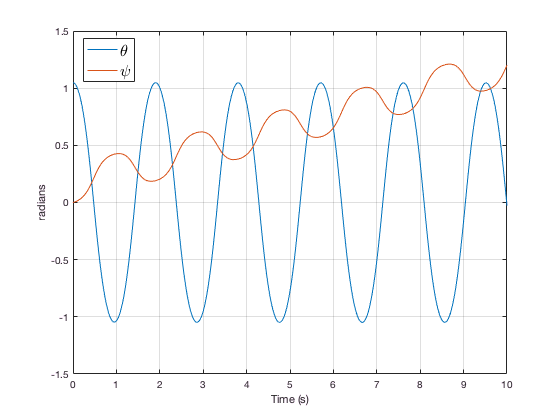

plot(T,Z(:,[1,3]))
grid on
ylabel('radians')
xlabel('Time (s)')
legend({'\theta','\psi'},'FontSize',16,'Location','best')